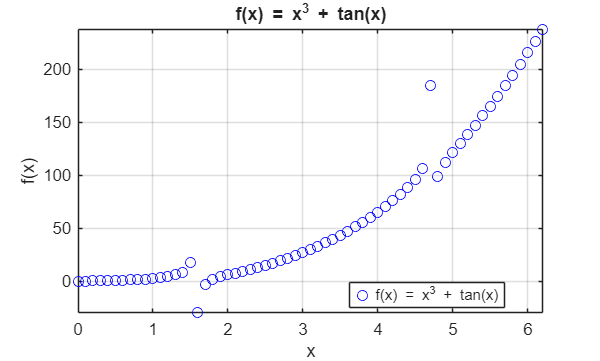

% 1 uzduotis
% a)

x = 0:0.1:2*pi;
f1 = x.^3 + tan(x);

figure ('Name', '1a uzduotis');
plot(x, f1, 'bo');
title('f(x) = x^3 + tan(x)');
xlabel('x');
ylabel('f(x)');
legend('f(x) = x^3 + tan(x)', 'Location', 'best');
axis([min(x) max(x) min(f1) max(f1)]);
grid on;

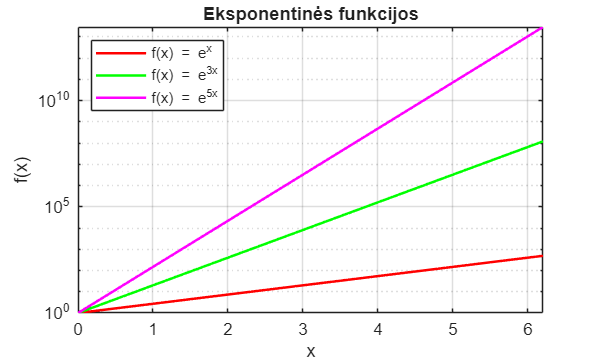


% b)

f2 = exp(x);
f3 = exp(3*x);
f4 = exp(5*x);

figure('Name', '1b uzduotis');
semilogy(x, f2, 'r-', x, f3, 'g-', x, f4, 'm-', 'LineWidth', 1.5);
title('Eksponentinės funkcijos');
xlabel('x');
ylabel('f(x)');
legend('f(x) = e^x', 'f(x) = e^{3x}', 'f(x) = e^{5x}', 'Location','northwest');
ymin = min([f2 f3 f4]);
ymax = max([f2 f3 f4]);
axis([min(x) max(x) ymin ymax]);
grid on;

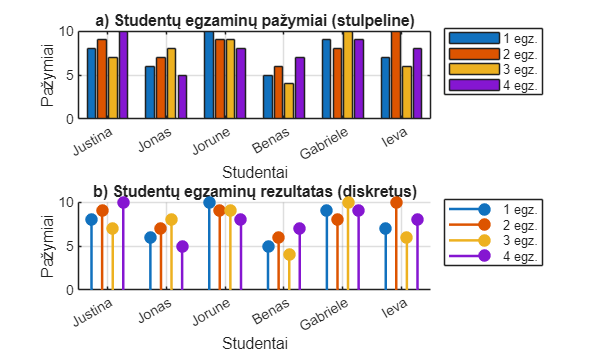


% 2 uzduotis
% a)

vardai = {'Justina', 'Jonas', 'Jorune', 'Benas', 'Gabriele', 'Ieva' };
egzam = {'1 egz.', '2 egz.', '3 egz.', '4 egz.'};

paz = [ 8  9  7 10;
        6  7  8  5;
       10  9  9  8;
        5  6  4  7;
        9  8 10  9;
        7 10  6  8];
[nStud, nEgz] = size(paz);

figure('Name', '2 uzduotis');

%pirmas grafikas
subplot(2, 1, 1);
bar(paz);
set(gca, 'XTick', 1:nStud, 'XTickLabel', vardai);
xlabel('Studentai');
ylabel('Pažymiai');
legend(egzam, 'Location', 'northeastoutside');
title('a) Studentų egzaminų pažymiai (stulpeline)');
axis([0.5 nStud+0.5 0 10]);
grid on;

%antras grafikas
subplot(2, 1, 2);
hold on;
spalvos = lines(nEgz);
poslinkis = linspace(-0.27, 0.27, nEgz);
for k = 1:nEgz
    stem((1:nStud) + poslinkis(k), paz(:, k), 'filled', ...
        'Color', spalvos(k, :), 'LineWidth', 1.5);
    end
hold off;
set(gca, 'XTick', 1:nStud, 'XTickLabel', vardai);
xlabel('Studentai');
ylabel('Pažymiai');
legend(egzam, 'Location', 'northeastoutside');
title('b) Studentų egzaminų rezultatas (diskretus)');
axis([0.5 nStud+0.5 0 10]);
grid on;